clear
syms x1 x2 x3 u 'real'
f = [x1 + x2;
     x1*x2^2 - x1 + x3;
     u]

$$f = \left(\begin{array}{c} x_{1}+x_{2}\\ x_{1}\,{x_{2}}^{2}-x_{1}+x_{3}\\ u \end{array}\right)$$

h = -x1^3 + x2

$$h = x_{2}-{x_{1}}^{3}$$

A = [diff(f,x1) diff(f,x2) diff(f,x3)]

$$A = \left(\begin{array}{ccc} 1 & 1 & 0\\ {x_{2}}^{2}-1 & 2\,x_{1}\,x_{2} & 1\\ 0 & 0 & 0 \end{array}\right)$$

A = subs(A,[x1,x2,x3,u],[0,0,0,0])

$$A = \left(\begin{array}{ccc} 1 & 1 & 0\\ -1 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

B = diff(f,u)

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

B = subs(B,[x1,x2,x3,u],[0,0,0,0])

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

C = [diff(h,x1) diff(h,x2) diff(h,x3)]

$$C = \left(\begin{array}{ccc} -3\,{x_{1}}^{2} & 1 & 0 \end{array}\right)$$

C = subs(C,[x1,x2,x3],[0,0,0])

$$C = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

Ob = [C; C*A; C*A^2]
rank(Ob)
double(cond(Ob))
Co = [B A*B A^2*B]
rank(Co)
double(cond(Co))

syms h1 h2 h3 lambda
H = [h1; h2; h3]

$$H = \left(\begin{array}{c} h_{1}\\ h_{2}\\ h_{3} \end{array}\right)$$

A_HC = lambda*eye(3) - (A - H*C)

$$A\_HC = \left(\begin{array}{ccc} \lambda -1 & h_{1}-1 & 0\\ 1 & h_{2}+\lambda & -1\\ 0 & h_{3} & \lambda \end{array}\right)$$

poly = collect(det(A_HC),lambda)

$$poly = \lambda^{3}+\left(h_{2}-1\right)\,\lambda^{2}+\left(h_{3}-h_{2}-h_{1}+1\right)\,\lambda -h_{3}$$

% subs(poly,[h1,h2,h3],[-7,4,-1])

$$ans = \lambda^{3}+3\,\lambda^{2}+3\,\lambda +1$$

syms k1 k2 k3 lambda
K = [k1 k2 k3]

$$K = \left(\begin{array}{ccc} k_{1} & k_{2} & k_{3} \end{array}\right)$$

A_BK = lambda*eye(3) - (A - B*K)

$$A\_BK = \left(\begin{array}{ccc} \lambda -1 & -1 & 0\\ 1 & \lambda & -1\\ k_{1} & k_{2} & k_{3}+\lambda \end{array}\right)$$

poly = collect(det(A_BK),lambda)

$$poly = \lambda^{3}+\left(k_{3}-1\right)\,\lambda^{2}+\left(k_{2}-k_{3}+1\right)\,\lambda +k_{1}-k_{2}+k_{3}$$

% subs(poly,[k1,k2,k3],[3,6,4])

$$ans = \lambda^{3}+3\,\lambda^{2}+3\,\lambda +1$$

K = place(double(A),double(B),[-1-0.001*1j -1+0.001*1j -1])

K =     3.0000    6.0000    4.0000


H = place(double(A)',double(C)',[-1-0.001*1j -1+0.001*1j -1])'

H =    -7.0000
    4.0000
   -1.0000


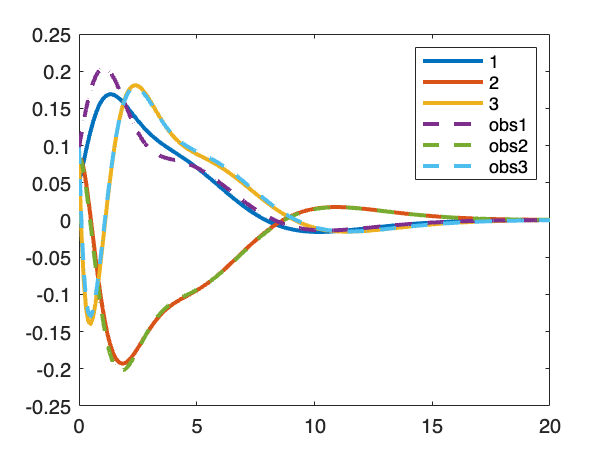

t = 0:0.1:20;
N = length(t);

x0 = [0.1-0.05*rand(1,3) 0.1-0.05*rand(1,3)];

[~,xsol] = ode45(@(t,x)sys(t,x,K,H),t,x0);

function dxdt = sys(~,x,K,H)
dxdt = zeros(6,1);
A = [1 1 0; -1 0 1; 0 0 0];
B = [0; 0; 1];
C = [0 1 0];
xhat = [x(4); x(5); x(6)];
u = -K*xhat;
dxdt(1) = x(1) + x(2);
dxdt(2) = x(1)*x(2)^2 - x(1) + x(3);
dxdt(3) = u;
y = -x(1)^3 + x(2);
xhatdot = A*xhat + B*u + H*(y - C*xhat);
dxdt(4) = xhatdot(1);
dxdt(5) = xhatdot(2);
dxdt(6) = xhatdot(3);
end

plot(t,xsol(:,1:3),'Linewidth',2)
hold on
plot(t,xsol(:,4:6),'--','Linewidth',2)
hold off
legend('1','2','3','obs1','obs2','obs3')